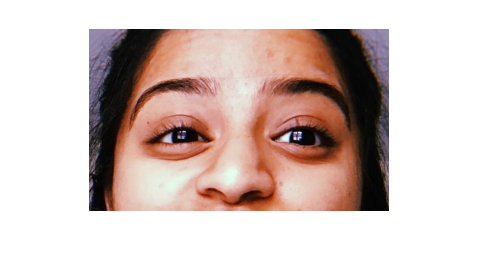

clear;

%Problem Number 1
tower = imread( 'tow', 'png' );
imshow( tower )


%k-means segmentation
k = 10

k = 10

clusters = random_centers( tower, k );

%Change the image into an array of RGBPoints
W = size(tower, 2);
H = size(tower, 1);
points(H, W) = RGBPoint( tower(H,W,1), tower(H,W,2), tower(H,W,3) );


for y = 1:H
    for x = 1:W
        points(y, x) = RGBPoint( tower(y,x,1), tower(y,x,2), tower(y,x,3) );
    end
end

%Clean up the environment
clear tower;

%Begin the while loop
iterate = true;
while( iterate )
    
%Find out which cluster each point is in and add that point to the working
%average of that cluster
cluster_amount = zeros(k, 1);
cluster_average = zeros(k, 3);
for y = 1:H
    for x = 1:W
        points(y, x) = points(y, x).find_cluster( clusters );
        c = points(y, x).getcluster();
        cluster_average(c, 1) = (cluster_average(c, 1) * cluster_amount(c) + points(y,x).getr()) / (cluster_amount(c) + 1);
        cluster_average(c, 2) = (cluster_average(c, 2) * cluster_amount(c) + points(y,x).getg()) / (cluster_amount(c) + 1);
        cluster_average(c, 3) = (cluster_average(c, 3) * cluster_amount(c) + points(y,x).getb()) / (cluster_amount(c) + 1);
        cluster_amount( c ) = cluster_amount(c) + 1;
    end
end

%Create usable points out of the averages of each cluster
new_clusters(k) = RGBPoint();
for i = 1:k
    new_clusters(i) = RGBPoint( round( cluster_average(i, 1)),  round( cluster_average(i, 2)),  round( cluster_average(i, 3)) );
end

thresh = 150; %If RGB-Distance between two points are below this threshold, we consider them the same point.
[iterate, distance_array] = same_clusters( clusters, new_clusters, thresh );
iterate = ~iterate;
disp( "Distances between SSD of old clusters averages and new ones" );
disp( distance_array );

clusters = new_clusters;

end %End of while loop

Distances between SSD of old clusters averages and new ones


         180
         221
        1129
          17
         219
          26
          42
         360
         297
          14



Distances between SSD of old clusters averages and new ones


   155
    61
   331
     6
     1
     2
    42
     2
    33
     5



Distances between SSD of old clusters averages and new ones


    70
     9
   131
     3
     1
     2
    22
     0
    19
     5




clear distance_array cluster_amount cluster_average i iterate new_clusters thresh

disp( "These are the resulting clusters of the k-means algorithm." )

These are the resulting clusters of the k-means algorithm.


for i = 1:k
    clusters(i).show()
end

R:197, G:117, B:91, C:0
R:121, G:109, B:136, C:0
R:67, G:42, B:34, C:0
R:220, G:163, B:149, C:0
R:229, G:203, B:192, C:0
R:226, G:183, B:169, C:0
R:213, G:146, B:127, C:0
R:231, G:225, B:215, C:0
R:154, G:76, B:47, C:0
R:15, G:11, B:10, C:0


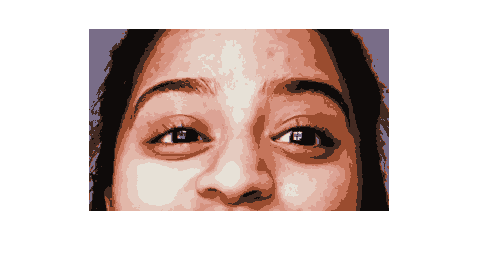


image = zeros( H, W, 3, 'uint8');
for y = 1:H
    for x = 1:W
        c = points(y, x).getcluster();
        image(y, x, 1) = uint8(clusters(c).getr());
        image(y, x, 2) = uint8(clusters(c).getg());
        image(y, x, 3) = uint8(clusters(c).getb());
    end
end

imshow( image );


clear k clusters points c clusters H i image k points W x y